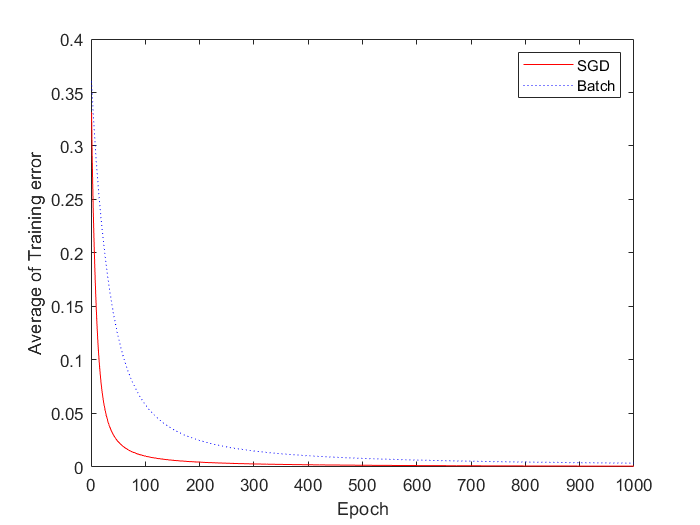

clear all
           
X = [ 0 0 1;
      0 1 1;
      1 0 1;
      1 1 1;
    ];

D = [ 0
      0
      1
      1
    ];


E1 = zeros(1000, 1);
E2 = zeros(1000, 1);

W1 = 2*rand(1, 3) - 1;
W2 = W1;

for epoch = 1:1000           % train
  W1 = DeltaSGD(W1, X, D);
  W2 = DeltaBatch(W2, X, D);

  es1 = 0;
  es2 = 0;
  N   = 4;
  for k = 1:N
    x = X(k, :)';
    d = D(k);
    
    v1  = W1*x;
    y1  = Sigmoid(v1);
    es1 = es1 + (d - y1)^2;
    
    v2  = W2*x;
    y2  = Sigmoid(v2);
    es2 = es2 + (d - y2)^2;
  end
  E1(epoch) = es1 / N;
  E2(epoch) = es2 / N;
end

plot(E1, 'r')
hold on
plot(E2, 'b:')
xlabel('Epoch')
ylabel('Average of Training error')
legend('SGD', 'Batch')